## Problem 1

For each of the following distributions, do: 

- plot the probability density function (PDF) based on the analytical expression. The PDF must appear smooth enough and without apparent signs of discretization.

- plot the cumulative distribution function (CDF) using Riemann-sum approximation. The CDF must appear smooth enough and without apparent signs of discretization. 

- use Riemann-sum approximations to compute the approximate variance (if finite) within a tolerance of 0.01 of its true value known analytically. 

Laplace PDF with location parameter $µ := 2$ and scale parameter $b := 2$.

mu = 2;
b = 2;
int_size = 0.5;

#### PDF

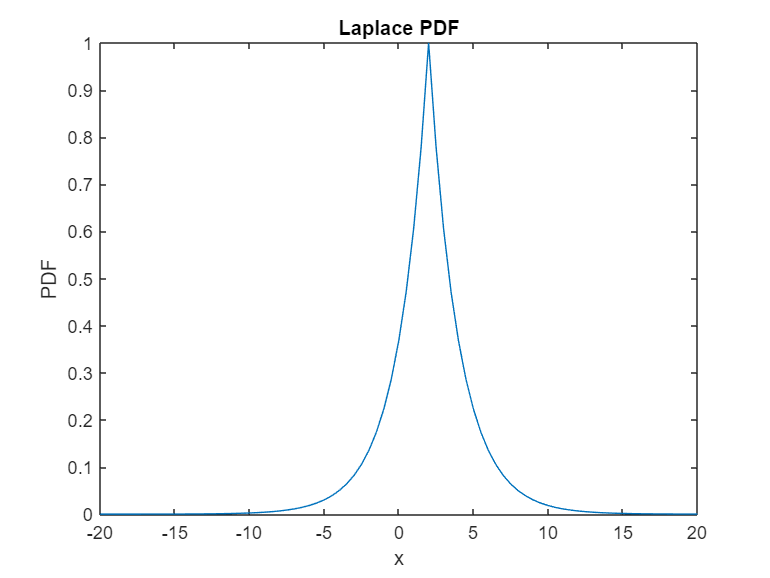

x = -20:int_size:20;
y_pdf = (exp(-abs(x-mu)/b))/2*b;

plot(x, y_pdf), xlabel("x"), ylabel("PDF"), title("Laplace PDF");

#### CDF

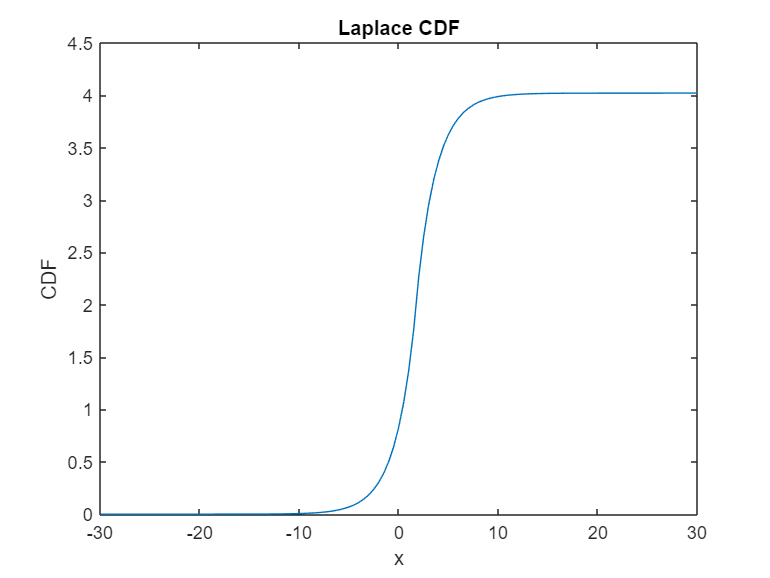

x = -30:int_size:30;
y_pdf = (exp(-abs(x-mu)/b))/2*b;

y_cdf = cumsum(y_pdf)*int_size;

plot(x, y_cdf), xlabel("x"), ylabel("CDF"), title("Laplace CDF");

#### VAR

x = -50:int_size:50;
y_pdf = (exp(-abs(x-mu)/b))/2*b;

mean_2 = sum(x.*x.*y_pdf*int_size);
mean = sum(x.*y_pdf*int_size);

var = mean_2 - (mean^2);
disp(var);

  -16.5850



Gumbel PDF  with location parameter $µ := 1$ and scale parameter $\beta  := 2$.

mu = 1;
b = 2;
int_size = 0.2;

#### PDF

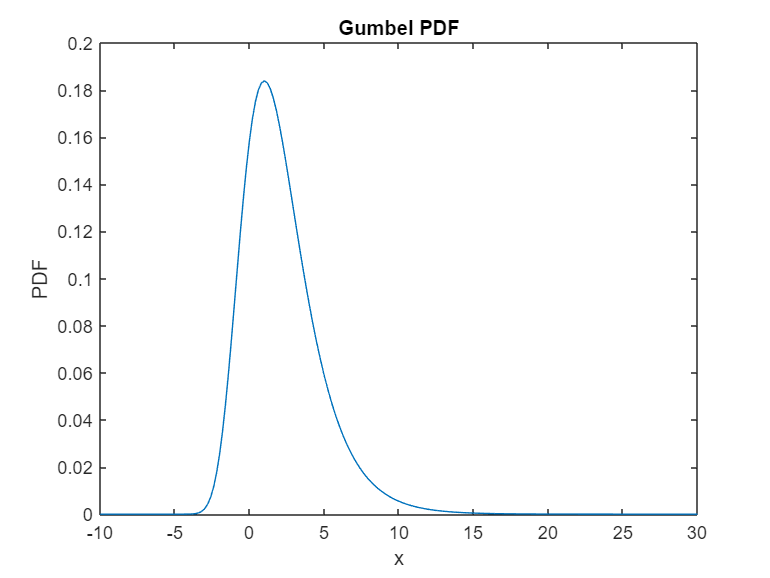

x = -10:int_size:30;
z = (x-mu)/b;
y_pdf = exp(-(z + exp(-z)))/b;

plot(x, y_pdf), xlabel("x"), ylabel("PDF"), title("Gumbel PDF");

#### CDF

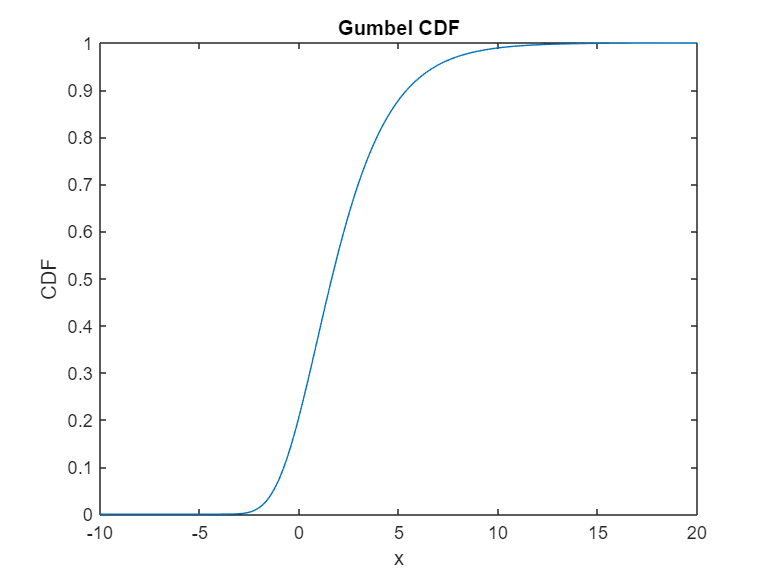

x = -10:int_size:20;
z = (x-mu)/b;
y_pdf = exp(-(z + exp(-z)))/b;

y_cdf = cumsum(y_pdf)*int_size;

plot(x, y_cdf), xlabel("x"), ylabel("CDF"), title("Gumbel CDF");

#### VAR

x = -20:int_size:40;
z = (x-mu)/b;
y_pdf = exp(-(z + exp(-z)))/b;

mean_2 = sum(x.*x.*y_pdf*int_size);
mean = sum(x.*y_pdf*int_size);

var = mean_2 - (mean^2);
disp(var);

    6.5797



Cauchy PDF with location parameter $x_0 := 0$ and scale parameter $\gamma  := 1$. 

x_0 = 0;
gam = 1;
p = pi;
int_size = 0.1;

#### PDF

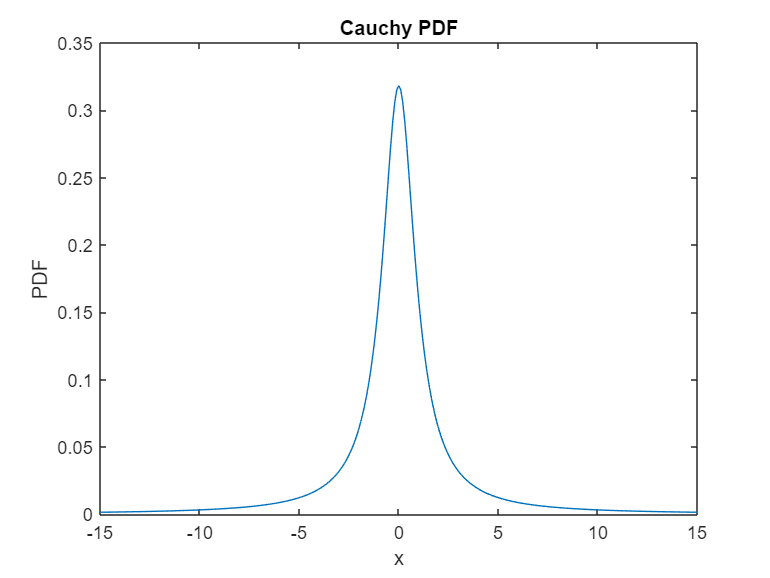

x = -15:int_size:15;
z = 1+((x-x_0)/gam).^2;

y_pdf = 1./(p*gam*z);



plot(x, y_pdf), xlabel("x"), ylabel("PDF"), title("Cauchy PDF");

#### CDF

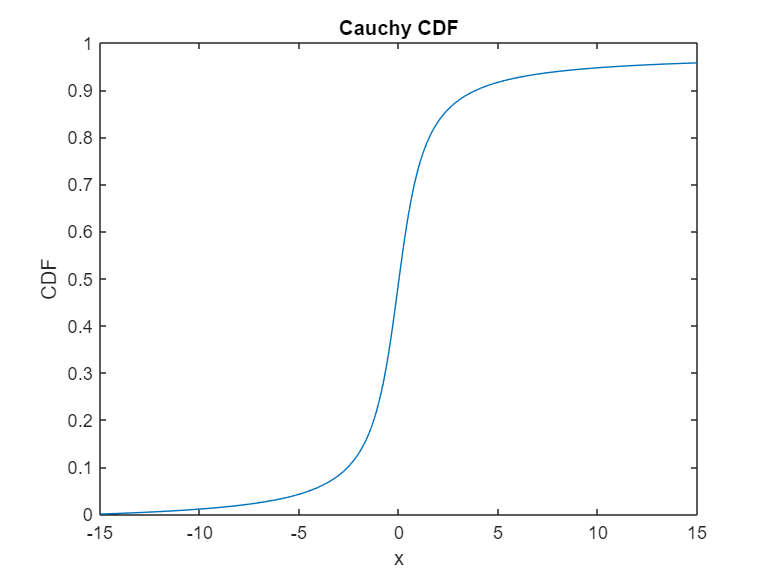

x = -15:int_size:15;
z = 1+((x-x_0)/gam).^2;

y_pdf = 1./(p*gam*z);

y_cdf = cumsum(y_pdf)*int_size;

plot(x, y_cdf), xlabel("x"), ylabel("CDF"), title("Cauchy CDF");

#### VAR